%papildoma var 2

t = 0 : 0.002 : 1.5;
A_s=4;
f = 3;
sigma = 1;
U1 = 2.5;
U2 = 1.5;

s = A_s*sin(2*pi*f*t);
n = sigma*randn(size(t));
s_n = s + n;

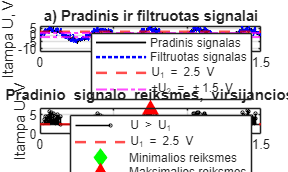

s_filtr = s_n;
s_filtr(abs(s_filtr)<U2) = 0;

idx = s_n > U1;
t_atr = t(idx);
atrinktos = s_n(idx);

[u_min, i_min] = min(atrinktos);
[u_max, i_max] = max(atrinktos);


figure('Name', 'Papildoma uzduotis');

subplot(2, 1, 1);
plot(t, s_n,     'k-', 'LineWidth', 1);  hold on;
plot(t, s_filtr, 'b:', 'LineWidth', 1.5);
yline(U1,  'r--', 'LineWidth', 1.5);
yline(U2,  'm-.', 'LineWidth', 1.2);
yline(-U2, 'm-.', 'LineWidth', 1.2, 'HandleVisibility', 'off');
hold off;
title('a) Pradinis ir filtruotas signalai');
xlabel('Laikas t, s');
ylabel('Itampa U, V');
legend('Pradinis signalas', 'Filtruotas signalas', 'U_1 = 2.5 V', '\pmU_2 = \pm1.5 V', 'Location', 'southeast');
axis([min(t) max(t) min(s_n)-5 max(s_n)+0.5]);
grid on;

subplot(2, 1, 2);
stem(t_atr, atrinktos, 'k', 'MarkerSize', 2, 'BaseValue', U1); hold on;
yline(U1, 'r--', 'LineWidth', 1.5);
plot(t_atr(i_min), u_min, 'gd', 'MarkerFaceColor', 'g', 'MarkerSize', 8);
plot(t_atr(i_max), u_max, 'r^', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
hold off;
title('b) Pradinio signalo reiksmes, virsijancios U_1');
xlabel('Laikas t, s');
ylabel('Itampa U, V');
legend('U > U_1', 'U_1 = 2.5 V', 'Minimalios reiksmes', 'Maksimalios reiksmes', 'Location', 'southeast');
axis([min(t) max(t) 0 max(s_n)+0.5]);
grid on;